# DD Costas Loop

## Constant doppler shift, first order FLL, single SNR, gamma = 0.01, TRACKING

Doppler shift

No phase offset

Fixed EbN0

ONLY TRACKING (only avoiding noise)



 ===== RESULTS ======
Number of transmitted bits = 100000

Carrier frequency [MHz] = 450.00

Doppler (at t = 0) [Hz] = 10000.00

Linear Doppler variation
Doppler variation rate [Hz] = 0.00

Rb = 1000000
Eb/N0: 7.99 dB 
Es/N0: 11.00 dB 
SER = 3.600000e-04
BER = 3.600000e-04
Frequency mean = 9.999981e+03
Frequency std = 3.883100e-02


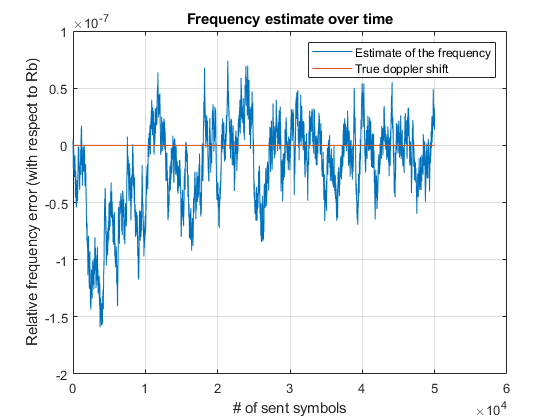

clear all;
close all;
N = 1e5;
gamma = 0.01; %For the loop filter;
doppler = 10e3;
alpha = pi/8;

tic
cont_first_order(6.3,450e6,1e6,true,false,N,doppler,0,0,doppler,gamma,alpha);

toc;

Elapsed time is 46.693207 seconds.


## Constant doppler shift, first order FLL, single SNR, gamma = 0.01, TRACKING, CHANGING THE Symbol Rate

Doppler shift

No phase offset

Fixed EbN0

ONLY TRACKING (only avoiding noise)

clear all;
close all;
N = 1e5;
gamma = 0.01; %For the loop filter;
doppler = 10e3;
alpha = pi/8;

tic
cont_first_order(6.3,450e6,2e6,true,false,N,doppler,0,0,doppler,gamma,alpha);

## Constant doppler shift, first order FLL, single SNR, gamma = 0.01, ACQUISITION

Doppler shift

No phase offset

Fixed EbN0

Tracking and acquisition (only avoiding noise)

clear all;
close all;
N = 1e5;
gamma = 0.01; %For the loop filter;
doppler = 120;
alpha = pi/8;

tic
cont_first_order(6.3,450e6,1e6,true,false,N,doppler,0,0,0,gamma,alpha);
toc;

## Constant doppler shift, first order FLL, single SNR, gamma = 10, ACQUISITION

Doppler shift

No phase offset

Fixed EbN0

Tracking and acquisition (only avoiding noise)

clear all;
close all;
N = 1e6;
gamma = 10; %For the loop filter;
doppler = 10e3;
alpha = pi/8;

tic
cont_first_order(6.3,450e6,1e6,true,false,N,doppler,0,0,0,gamma,alpha);

## Conclusiones

El tracking constante lo hace bien, la adquisición puede hacerla pero es necesario que el gamma sea alto si el doppler shift es alto. En principio no se va a usar para adquisición pero se podría mejorar el algoritmo haciendo el step adaptativo. Se puede comprobar que el error en la frecuencia es relativo al reloj de símbolo